% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc; 
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-22/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Blood_Plasma1(40x,495mW,Well1)_2500_24_2024-07-22-17.00.33.803.csv";
file_path = data_path+file_name;
blood_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well1)_2500_24_2024-07-22-17.02.06.960.csv";
file_path = strcat(data_path,file_name);
blood_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well1)_2500_24_2024-07-22-17.03.38.537.csv";
file_path = strcat(data_path,file_name);
blood_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well1)_2500_24_2024-07-22-17.05.20.193.csv";
file_path = strcat(data_path,file_name);
blood_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well1)_2500_24_2024-07-22-17.06.54.803.csv";
file_path = strcat(data_path,file_name);
blood_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well1)_2500_24_2024-07-22-17.08.35.920.csv";
file_path = strcat(data_path,file_name);
blood_6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well1)_2500_24_2024-07-22-17.11.26.313.csv";
file_path = strcat(data_path,file_name);
blood_7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well1)_2500_24_2024-07-22-17.13.03.390.csv";
file_path = strcat(data_path,file_name);
blood_8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well1)_2500_24_2024-07-22-17.14.41.587.csv";
file_path = strcat(data_path,file_name);
blood_9 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well1)_2500_24_2024-07-22-17.16.15.400.csv";
file_path = strcat(data_path,file_name);
blood_10 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_100_2024-07-22-14.58.35.077.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_100_2024-07-22-15.12.29.507.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_100_2024-07-22-15.08.33.957.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
blood_1(:, blood_1(1, :) <= t1) = [];
blood_1(:, blood_1(1, :) >= t2) = [];
blood_2(:, blood_2(1, :) <= t1) = [];
blood_2(:, blood_2(1, :) >= t2) = [];
blood_3(:, blood_3(1, :) <= t1) = [];
blood_3(:, blood_3(1, :) >= t2) = [];
blood_4(:, blood_4(1, :) <= t1) = [];
blood_4(:, blood_4(1, :) >= t2) = [];
blood_5(:, blood_5(1, :) <= t1) = [];
blood_5(:, blood_5(1, :) >= t2) = [];
blood_6(:, blood_6(1, :) <= t1) = [];
blood_6(:, blood_6(1, :) >= t2) = [];
blood_7(:, blood_7(1, :) <= t1) = [];
blood_7(:, blood_7(1, :) >= t2) = [];
blood_8(:, blood_8(1, :) <= t1) = [];
blood_8(:, blood_8(1, :) >= t2) = [];
blood_9(:, blood_9(1, :) <= t1) = [];
blood_9(:, blood_9(1, :) >= t2) = [];
blood_10(:, blood_10(1, :) <= t1) = [];
blood_10(:, blood_10(1, :) >= t2) = [];

shifts = wavenumber;

blood1 = blood_1(2:end, :);
blood2 = blood_2(2:end, :);
blood3 = blood_3(2:end, :);
blood4 = blood_4(2:end, :);
blood5 = blood_5(2:end, :);
blood6 = blood_6(2:end, :);
blood7 = blood_7(2:end, :);
blood8 = blood_8(2:end, :);
blood9 = blood_9(2:end, :);
blood10 = blood_10(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

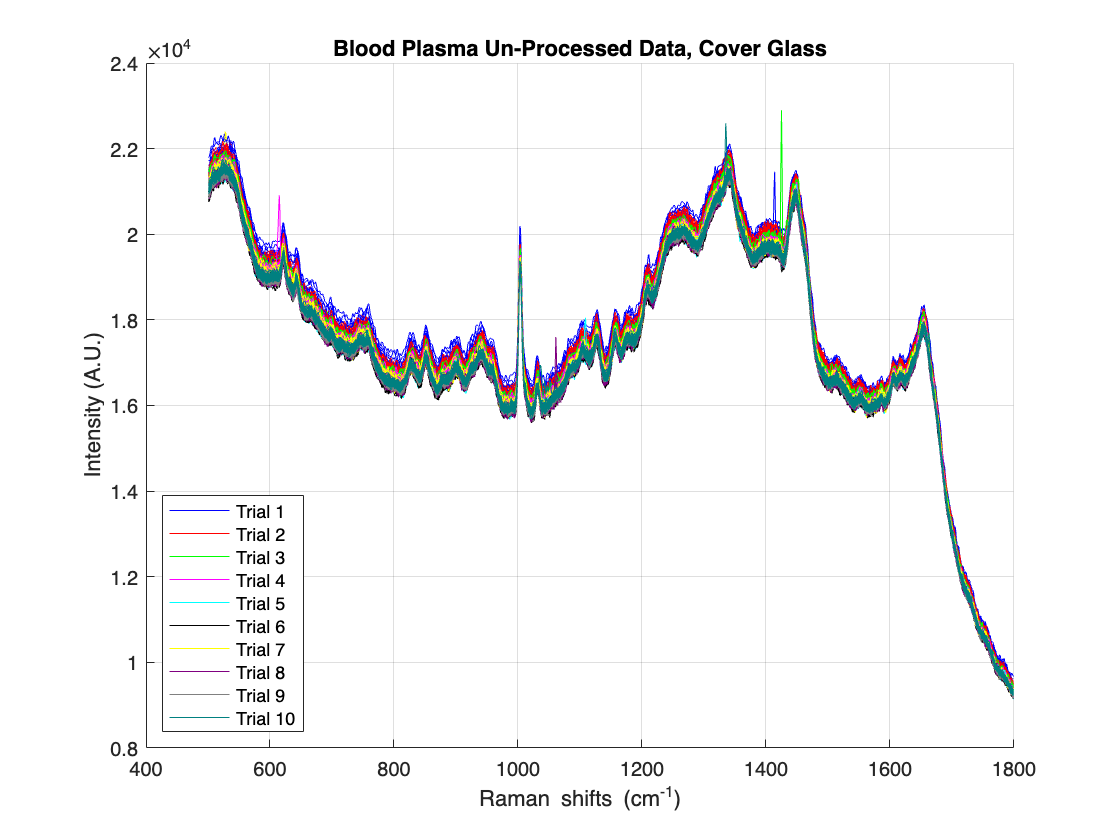

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1(1,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2(1,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3(1,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4(1,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5(1,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6(1,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7(1,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8(1,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9(1,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10(1,:), 'Color', [0 0.5 0.5]); % Teal
plot(wavenumber, blood1(2:end,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2(2:end,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3(2:end,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4(2:end,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5(2:end,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6(2:end,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7(2:end,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8(2:end,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9(2:end,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10(2:end,:), 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

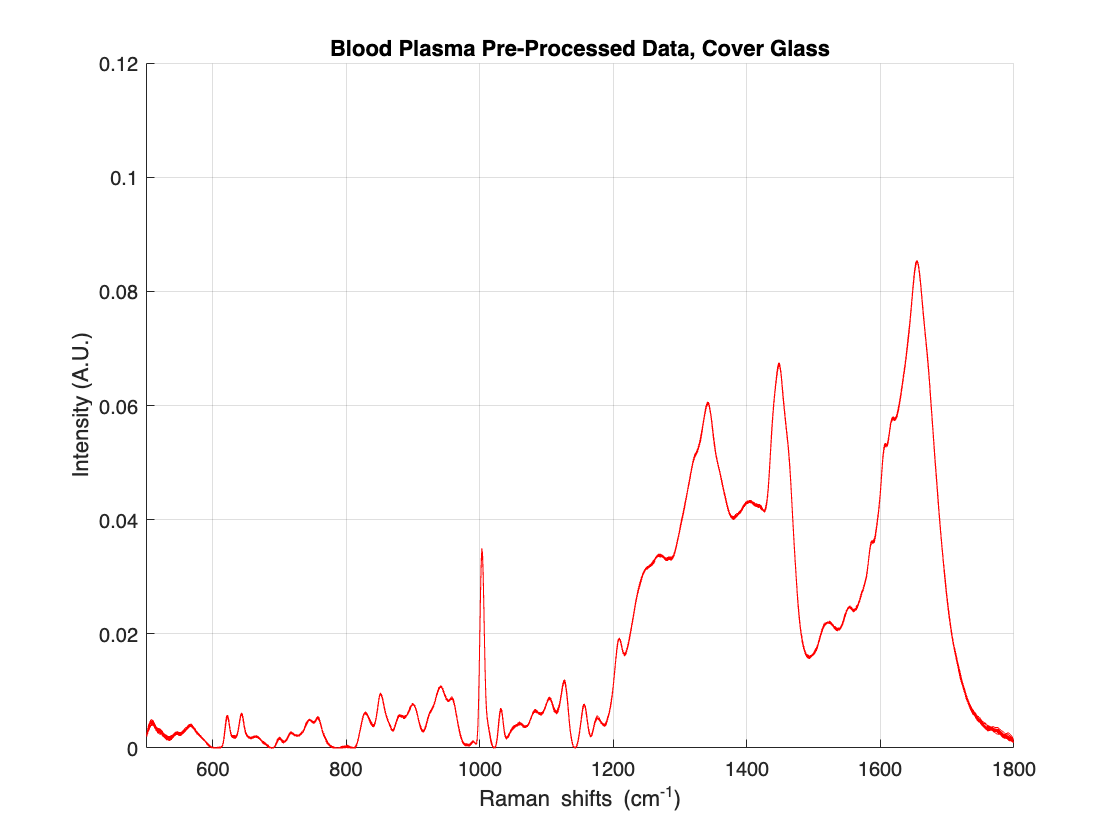

% Preprocessing the data

pro_blood1 = apply(blood1, [6,1,10,11,8,2,5,6,7]);
pro_blood2 = apply(blood2, [6,1,10,11,8,2,5,6,7]);
pro_blood3 = apply(blood3, [6,1,10,11,8,2,5,6,7]);
pro_blood4 = apply(blood4, [6,1,10,11,8,2,5,6,7]);
pro_blood5 = apply(blood5, [6,1,10,11,8,2,5,6,7]);
pro_blood6 = apply(blood6, [6,1,10,11,8,2,5,6,7]);
pro_blood7 = apply(blood7, [6,1,10,11,8,2,5,6,7]);
pro_blood8 = apply(blood8, [6,1,10,11,8,2,5,6,7]);
pro_blood9 = apply(blood9, [6,1,10,11,8,2,5,6,7]);
pro_blood10 = apply(blood10, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood = [blood1;blood2;blood3;blood4;blood5;blood6;blood7;blood8;blood9;blood10];
pro_blood = apply(blood, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Cover Glass');
xlim([500 1800]);
ylim([0 0.12]);
hold off;

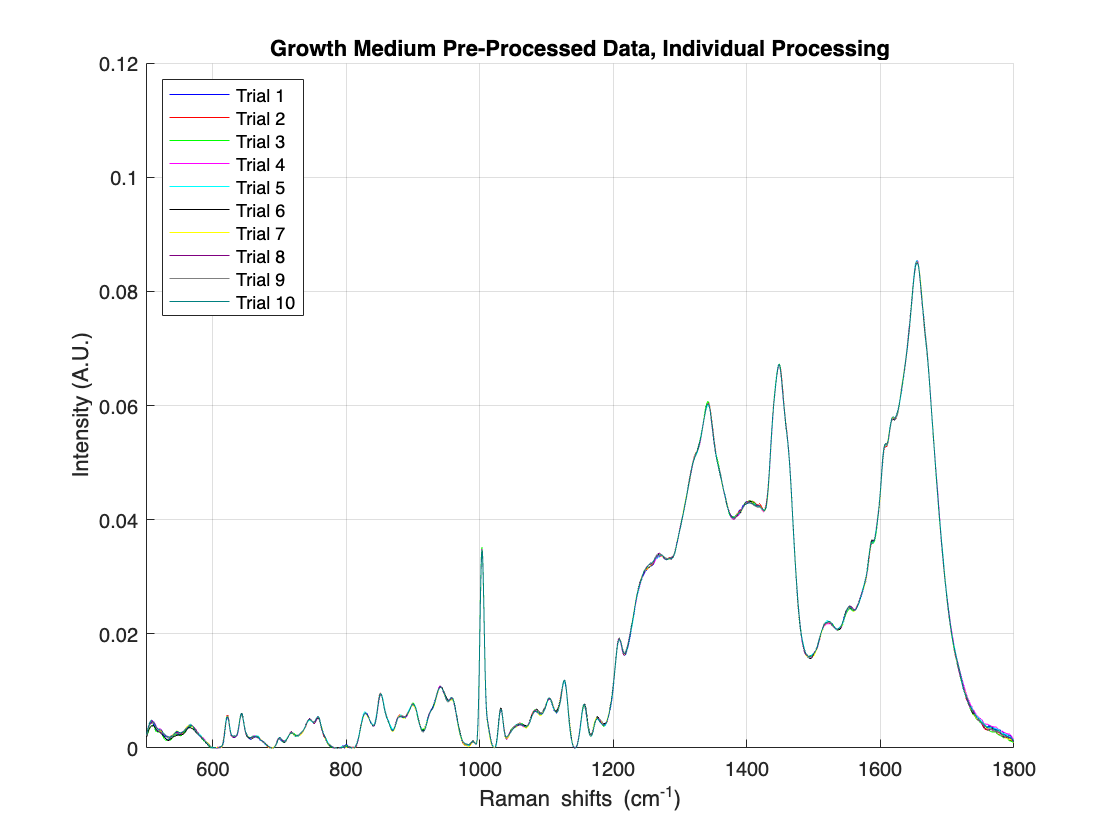

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1, 'Color', [0 0 1]); % Blue
plot(wavenumber, pro_blood2, 'Color', [1 0 0]); % Red
plot(wavenumber, pro_blood3, 'Color', [0 1 0]); % Green
plot(wavenumber, pro_blood4, 'Color', [1 0 1]); % Magenta
plot(wavenumber, pro_blood5, 'Color', [0 1 1]); % Cyan
plot(wavenumber, pro_blood6, 'Color', [0 0 0]); % Black
plot(wavenumber, pro_blood7, 'Color', [1 1 0]); % Yellow
plot(wavenumber, pro_blood8, 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, pro_blood9, 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, pro_blood10, 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Growth Medium Pre-Processed Data, Individual Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
xlim([500 1800]);
ylim([0 0.12]);
hold off;

% % Data for 1003 cm^-1 peak
% Trial1 = pro_blood1(:, 503);
% Trial2 = pro_blood2(:, 503);
% Trial3 = pro_blood3(:, 503);
% Trial4 = pro_blood4(:, 503);
% Trial5 = pro_blood5(:, 503);
% Trial6 = pro_blood6(:, 503);
% Trial7 = pro_blood7(:, 503);
% Trial8 = pro_blood8(:, 503);
% Trial9 = pro_blood9(:, 503);
% Trial10 = pro_blood10(:, 503);
% 
% % Calculate means
% av_Trial1 = mean(Trial1);
% av_Trial2 = mean(Trial2);
% av_Trial3 = mean(Trial3);
% av_Trial4 = mean(Trial4);
% av_Trial5 = mean(Trial5);
% av_Trial6 = mean(Trial6);
% av_Trial7 = mean(Trial7);
% av_Trial8 = mean(Trial8);
% av_Trial9 = mean(Trial9);
% av_Trial10 = mean(Trial10);
% 
% % Calculate standard deviations
% std_Trial1 = std(Trial1);
% std_Trial2 = std(Trial2);
% std_Trial3 = std(Trial3);
% std_Trial4 = std(Trial4);
% std_Trial5 = std(Trial5);
% std_Trial6 = std(Trial6);
% std_Trial7 = std(Trial7);
% std_Trial8 = std(Trial8);
% std_Trial9 = std(Trial9);
% std_Trial10 = std(Trial10);
% 
% % Number of spectra in each collection
% n_Trial1 = size(Trial1, 1);
% n_Trial2 = size(Trial2, 1);
% n_Trial3 = size(Trial3, 1);
% n_Trial4 = size(Trial4, 1);
% n_Trial5 = size(Trial5, 1);
% n_Trial6 = size(Trial6, 1);
% n_Trial7 = size(Trial7, 1);
% n_Trial8 = size(Trial8, 1);
% n_Trial9 = size(Trial9, 1);
% n_Trial10 = size(Trial10, 1);
% 
% % Perform t-tests between pairs
% [t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
% [t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
% [t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4] = perform_ttest(av_Trial1, av_Trial4, std_Trial1, std_Trial4, n_Trial1, n_Trial4);
% [t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5] = perform_ttest(av_Trial1, av_Trial5, std_Trial1, std_Trial5, n_Trial1, n_Trial5);
% [t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6] = perform_ttest(av_Trial1, av_Trial6, std_Trial1, std_Trial6, n_Trial1, n_Trial6);
% [t_Trial1_Trial7, p_Trial1_Trial7, df_Trial1_Trial7] = perform_ttest(av_Trial1, av_Trial7, std_Trial1, std_Trial7, n_Trial1, n_Trial7);
% [t_Trial1_Trial8, p_Trial1_Trial8, df_Trial1_Trial8] = perform_ttest(av_Trial1, av_Trial8, std_Trial1, std_Trial8, n_Trial1, n_Trial8);
% [t_Trial1_Trial9, p_Trial1_Trial9, df_Trial1_Trial9] = perform_ttest(av_Trial1, av_Trial9, std_Trial1, std_Trial9, n_Trial1, n_Trial9);
% [t_Trial1_Trial10, p_Trial1_Trial10, df_Trial1_Trial10] = perform_ttest(av_Trial1, av_Trial10, std_Trial1, std_Trial10, n_Trial1, n_Trial10);
% [t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);
% [t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4] = perform_ttest(av_Trial2, av_Trial4, std_Trial2, std_Trial4, n_Trial2, n_Trial4);
% [t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5] = perform_ttest(av_Trial2, av_Trial5, std_Trial2, std_Trial5, n_Trial2, n_Trial5);
% [t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6] = perform_ttest(av_Trial2, av_Trial6, std_Trial2, std_Trial6, n_Trial2, n_Trial6);
% [t_Trial2_Trial7, p_Trial2_Trial7, df_Trial2_Trial7] = perform_ttest(av_Trial2, av_Trial7, std_Trial2, std_Trial7, n_Trial2, n_Trial7);
% [t_Trial2_Trial8, p_Trial2_Trial8, df_Trial2_Trial8] = perform_ttest(av_Trial2, av_Trial8, std_Trial2, std_Trial8, n_Trial2, n_Trial8);
% [t_Trial2_Trial9, p_Trial2_Trial9, df_Trial2_Trial9] = perform_ttest(av_Trial2, av_Trial9, std_Trial2, std_Trial9, n_Trial2, n_Trial9);
% [t_Trial2_Trial10, p_Trial2_Trial10, df_Trial2_Trial10] = perform_ttest(av_Trial2, av_Trial10, std_Trial2, std_Trial10, n_Trial2, n_Trial10);
% [t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4] = perform_ttest(av_Trial3, av_Trial4, std_Trial3, std_Trial4, n_Trial3, n_Trial4);
% [t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5] = perform_ttest(av_Trial3, av_Trial5, std_Trial3, std_Trial5, n_Trial3, n_Trial5);
% [t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6] = perform_ttest(av_Trial3, av_Trial6, std_Trial3, std_Trial6, n_Trial3, n_Trial6);
% [t_Trial3_Trial7, p_Trial3_Trial7, df_Trial3_Trial7] = perform_ttest(av_Trial3, av_Trial7, std_Trial3, std_Trial7, n_Trial3, n_Trial7);
% [t_Trial3_Trial8, p_Trial3_Trial8, df_Trial3_Trial8] = perform_ttest(av_Trial3, av_Trial8, std_Trial3, std_Trial8, n_Trial3, n_Trial8);
% [t_Trial3_Trial9, p_Trial3_Trial9, df_Trial3_Trial9] = perform_ttest(av_Trial3, av_Trial9, std_Trial3, std_Trial9, n_Trial3, n_Trial9);
% [t_Trial3_Trial10, p_Trial3_Trial10, df_Trial3_Trial10] = perform_ttest(av_Trial3, av_Trial10, std_Trial3, std_Trial10, n_Trial3, n_Trial10);
% [t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5] = perform_ttest(av_Trial4, av_Trial5, std_Trial4, std_Trial5, n_Trial4, n_Trial5);
% [t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6] = perform_ttest(av_Trial4, av_Trial6, std_Trial4, std_Trial6, n_Trial4, n_Trial6);
% [t_Trial4_Trial7, p_Trial4_Trial7, df_Trial4_Trial7] = perform_ttest(av_Trial4, av_Trial7, std_Trial4, std_Trial7, n_Trial4, n_Trial7);
% [t_Trial4_Trial8, p_Trial4_Trial8, df_Trial4_Trial8] = perform_ttest(av_Trial4, av_Trial8, std_Trial4, std_Trial8, n_Trial4, n_Trial8);
% [t_Trial4_Trial9, p_Trial4_Trial9, df_Trial4_Trial9] = perform_ttest(av_Trial4, av_Trial9, std_Trial4, std_Trial9, n_Trial4, n_Trial9);
% [t_Trial4_Trial10, p_Trial4_Trial10, df_Trial4_Trial10] = perform_ttest(av_Trial4, av_Trial10, std_Trial4, std_Trial10, n_Trial4, n_Trial10);
% [t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6] = perform_ttest(av_Trial5, av_Trial6, std_Trial5, std_Trial6, n_Trial5, n_Trial6);
% [t_Trial5_Trial7, p_Trial5_Trial7, df_Trial5_Trial7] = perform_ttest(av_Trial5, av_Trial7, std_Trial5, std_Trial7, n_Trial5, n_Trial7);
% [t_Trial5_Trial8, p_Trial5_Trial8, df_Trial5_Trial8] = perform_ttest(av_Trial5, av_Trial8, std_Trial5, std_Trial8, n_Trial5, n_Trial8);
% [t_Trial5_Trial9, p_Trial5_Trial9, df_Trial5_Trial9] = perform_ttest(av_Trial5, av_Trial9, std_Trial5, std_Trial9, n_Trial5, n_Trial9);
% [t_Trial5_Trial10, p_Trial5_Trial10, df_Trial5_Trial10] = perform_ttest(av_Trial5, av_Trial10, std_Trial5, std_Trial10, n_Trial5, n_Trial10);
% [t_Trial6_Trial7, p_Trial6_Trial7, df_Trial6_Trial7] = perform_ttest(av_Trial6, av_Trial7, std_Trial6, std_Trial7, n_Trial6, n_Trial7);
% [t_Trial6_Trial8, p_Trial6_Trial8, df_Trial6_Trial8] = perform_ttest(av_Trial6, av_Trial8, std_Trial6, std_Trial8, n_Trial6, n_Trial8);
% [t_Trial6_Trial9, p_Trial6_Trial9, df_Trial6_Trial9] = perform_ttest(av_Trial6, av_Trial9, std_Trial6, std_Trial9, n_Trial6, n_Trial9);
% [t_Trial6_Trial10, p_Trial6_Trial10, df_Trial6_Trial10] = perform_ttest(av_Trial6, av_Trial10, std_Trial6, std_Trial10, n_Trial6, n_Trial10);
% [t_Trial7_Trial8, p_Trial7_Trial8, df_Trial7_Trial8] = perform_ttest(av_Trial7, av_Trial8, std_Trial7, std_Trial8, n_Trial7, n_Trial8);
% [t_Trial7_Trial9, p_Trial7_Trial9, df_Trial7_Trial9] = perform_ttest(av_Trial7, av_Trial9, std_Trial7, std_Trial9, n_Trial7, n_Trial9);
% [t_Trial7_Trial10, p_Trial7_Trial10, df_Trial7_Trial10] = perform_ttest(av_Trial7, av_Trial10, std_Trial7, std_Trial10, n_Trial7, n_Trial10);
% [t_Trial8_Trial9, p_Trial8_Trial9, df_Trial8_Trial9] = perform_ttest(av_Trial8, av_Trial9, std_Trial8, std_Trial9, n_Trial8, n_Trial9);
% [t_Trial8_Trial10, p_Trial8_Trial10, df_Trial8_Trial10] = perform_ttest(av_Trial8, av_Trial10, std_Trial8, std_Trial10, n_Trial8, n_Trial10);
% [t_Trial9_Trial10, p_Trial9_Trial10, df_Trial9_Trial10] = perform_ttest(av_Trial9, av_Trial10, std_Trial9, std_Trial10, n_Trial9, n_Trial10);
% 
% % Display results
% fprintf('t-test and p values for pairwise comparisons at 1003 cm^-1 peak:\n');
% fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);
% fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);
% fprintf('Trial 1 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4);
% fprintf('Trial 1 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5);
% fprintf('Trial 1 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6);
% fprintf('Trial 1 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial7, p_Trial1_Trial7, df_Trial1_Trial7);
% fprintf('Trial 1 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial8, p_Trial1_Trial8, df_Trial1_Trial8);
% fprintf('Trial 1 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial9, p_Trial1_Trial9, df_Trial1_Trial9);
% fprintf('Trial 1 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial10, p_Trial1_Trial10, df_Trial1_Trial10);
% fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);
% fprintf('Trial 2 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4);
% fprintf('Trial 2 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5);
% fprintf('Trial 2 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6);
% fprintf('Trial 2 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial7, p_Trial2_Trial7, df_Trial2_Trial7);
% fprintf('Trial 2 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial8, p_Trial2_Trial8, df_Trial2_Trial8);
% fprintf('Trial 2 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial9, p_Trial2_Trial9, df_Trial2_Trial9);
% fprintf('Trial 2 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial10, p_Trial2_Trial10, df_Trial2_Trial10);
% fprintf('Trial 3 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4);
% fprintf('Trial 3 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5);
% fprintf('Trial 3 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6);
% fprintf('Trial 3 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial7, p_Trial3_Trial7, df_Trial3_Trial7);
% fprintf('Trial 3 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial8, p_Trial3_Trial8, df_Trial3_Trial8);
% fprintf('Trial 3 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial9, p_Trial3_Trial9, df_Trial3_Trial9);
% fprintf('Trial 3 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial10, p_Trial3_Trial10, df_Trial3_Trial10);
% fprintf('Trial 4 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5);
% fprintf('Trial 4 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6);
% fprintf('Trial 4 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial7, p_Trial4_Trial7, df_Trial4_Trial7);
% fprintf('Trial 4 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial8, p_Trial4_Trial8, df_Trial4_Trial8);
% fprintf('Trial 4 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial9, p_Trial4_Trial9, df_Trial4_Trial9);
% fprintf('Trial 4 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial10, p_Trial4_Trial10, df_Trial4_Trial10);
% fprintf('Trial 5 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6);
% fprintf('Trial 5 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial7, p_Trial5_Trial7, df_Trial5_Trial7);
% fprintf('Trial 5 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial8, p_Trial5_Trial8, df_Trial5_Trial8);
% fprintf('Trial 5 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial9, p_Trial5_Trial9, df_Trial5_Trial9);
% fprintf('Trial 5 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial10, p_Trial5_Trial10, df_Trial5_Trial10);
% fprintf('Trial 6 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial7, p_Trial6_Trial7, df_Trial6_Trial7);
% fprintf('Trial 6 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial8, p_Trial6_Trial8, df_Trial6_Trial8);
% fprintf('Trial 6 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial9, p_Trial6_Trial9, df_Trial6_Trial9);
% fprintf('Trial 6 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial10, p_Trial6_Trial10, df_Trial6_Trial10);
% fprintf('Trial 7 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial8, p_Trial7_Trial8, df_Trial7_Trial8);
% fprintf('Trial 7 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial9, p_Trial7_Trial9, df_Trial7_Trial9);
% fprintf('Trial 7 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial10, p_Trial7_Trial10, df_Trial7_Trial10);
% fprintf('Trial 8 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial8_Trial9, p_Trial8_Trial9, df_Trial8_Trial9);
% fprintf('Trial 8 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial8_Trial10, p_Trial8_Trial10, df_Trial8_Trial10);
% fprintf('Trial 9 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial9_Trial10, p_Trial9_Trial10, df_Trial9_Trial10);

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end